%% Simulasi Sistem Robot Arm dengan Kontroler PID
% Script ini mensimulasikan respon step dari sebuah sendi robot
% yang dikontrol oleh kontroler PID dalam sistem closed-loop.

% --- Inisialisasi ---
clear;      % Hapus variabel dari workspace
clc;        % Bersihkan Command Window
close all;  % Tutup semua figure/plot yang terbuka

%% --- BAGIAN PARAMETER (UBAH NILAI DI SINI) ---
% Anda bisa mengubah nilai-nilai konstanta di bawah ini untuk melihat efeknya.

% Parameter Fisik Robot Arm
J = 0.1;   % Momen Inersia (kg.m^2)
B = 0.05;  % Koefisien Gesekan/Damping (N.m.s/rad)

% Gain Kontroler PID
Kp = 6;   % Gain Proportional
Ki = 2;   % Gain Integral
Kd = 4;   % Gain Derivative

%% --- Pembuatan Model Transfer Function ---
% Bagian ini secara otomatis membuat model berdasarkan parameter di atas.

% Mendefinisikan numerator (pembilang) dari CLTF
% Gcl(s) = (Kd*s^2 + Kp*s + Ki) / ...
num = [Kd, Kp, Ki];

% Mendefinisikan denominator (penyebut) dari CLTF
% ... / (J*s^3 + (B+Kd)*s^2 + Kp*s + Ki)
den = [J, (B + Kd), Kp, Ki];

% Membuat objek transfer function (TF)
sys_cl = tf(num, den);

% Menampilkan fungsi alih yang dihasilkan di Command Window
disp('Fungsi Alih Closed-Loop (CLTF) yang Dihasilkan:');

Fungsi Alih Closed-Loop (CLTF) yang Dihasilkan:


disp(sys_cl);

  tf with properties:

       Numerator: {[0 4 6 2]}
     Denominator: {[0.1000 4.0500 6 2]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



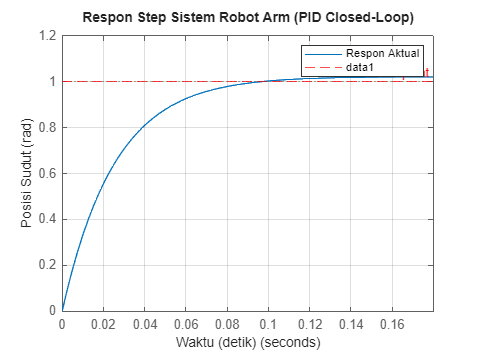



%% --- Simulasi dan Plotting ---
% Menjalankan simulasi respon step dan menampilkan hasilnya dalam bentuk plot.

figure;  % Membuat figure baru untuk plot
step(sys_cl); % Menjalankan dan mem-plot respon step dari sistem

% --- Mempercantik Plot ---
grid on; % Menambahkan grid
title('Respon Step Sistem Robot Arm (PID Closed-Loop)');
xlabel('Waktu (detik)');
ylabel('Posisi Sudut (rad)');
legend('Respon Aktual');

% Menambahkan garis referensi di y=1 untuk melihat setpoint
yline(1,'--r','Setpoint'); 


%% --- Analisis Performa (Opsional) ---
% Menghitung dan menampilkan karakteristik performa dari respon step.

% Hitung informasi step response (RiseTime, SettlingTime, Overshoot, etc.)
S = stepinfo(sys_cl);

% Tampilkan di Command Window
disp(' '); % Baris kosong untuk pemisah

disp('Karakteristik Performa Sistem:');

Karakteristik Performa Sistem:


disp(S);

         RiseTime: 0.0513
    TransientTime: 0.2935
     SettlingTime: 0.2935
      SettlingMin: 0.9021
      SettlingMax: 1.0216
        Overshoot: 2.1631
       Undershoot: 0
             Peak: 1.0216
         PeakTime: 0.1914




% Cek kondisi stabilitas Routh-Hurwitz
% (B + Kd) * Kp > J * Ki
stability_check = (B + Kd) * Kp - J * Ki;
if stability_check > 0
    disp('Kondisi stabilitas Routh-Hurwitz TERPENUHI.');
else
    disp('PERINGATAN: Kondisi stabilitas Routh-Hurwitz TIDAK TERPENUHI. Sistem mungkin tidak stabil!');
end

Kondisi stabilitas Routh-Hurwitz TERPENUHI.
